Q1 a)

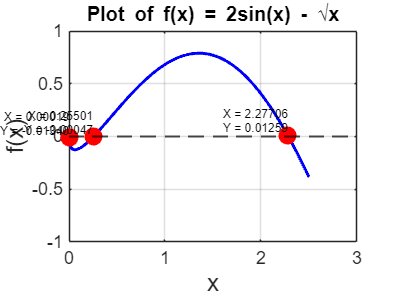

f = @(x) 2 * sin(x) - sqrt(x);


x_values = linspace(0, 2.5, 500);
f_values = f(x_values);

fig = figure;
plot(x_values, f_values, 'Color', [0, 0, 1], 'LineWidth', 1.5);
hold on;

yline(0, 'LineStyle', '--', 'Color', [0, 0, 0], 'LineWidth', 1);

critical_points_x = [0.00019, 0.25501, 2.27706];
critical_points_y = f(critical_points_x);

scatter(critical_points_x, critical_points_y, 80, 'MarkerFaceColor', [1, 0, 0], 'MarkerEdgeColor', [1, 0, 0]);

for i = 1:length(critical_points_x)
    text(critical_points_x(i), critical_points_y(i), ...
         sprintf('X = %.5f\nY = %.5f', critical_points_x(i), critical_points_y(i)), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'FontSize', 8);
end

title({'Graph of f(x) = 2sin(x) - \surdx'}, 'FontSize', 12);
xlabel('x-axis', 'FontSize', 12);
ylabel('f(x) values', 'FontSize', 12);

   k      xk


    0  0.220000


    1  0.236726
    2  0.245738
    3  0.250471
    4  0.252923
    5  0.254186
    6  0.254833
    7  0.255165
    8  0.255335
    9  0.255422
   10  0.255466
   11  0.255489
   12  0.255500
   13  0.255506
   14  0.255509


Final solution = 0.25551 to 5 decimal places



ylim([-1, 1]);
yticks(-1:0.5:1);

grid minor;
hold off;


Rearrangement 1:

2 sin(x) - $\sqrt{x\;}$ = 0

sin(x) = $\sqrt{x}$ / 2 

x = arcsin($\sqrt{x}$ / 2 ) 

clc;

  k     xk


    0  2.260000


    1  2.291010
    2  2.283183
    3  2.285160
    4  2.284661
    5  2.284787
    6  2.284755
    7  2.284763
    8  2.284761


Final solution = 2.28476 to 5 decimal places


clear;

iteration = 0;
current_x = 0.22;
tolerance = 1;

fprintf('Iteration    x\n');
fprintf('%9i%10.6f\n', iteration, current_x);

while tolerance > 0.5e-5
    previous_x = current_x;
    current_x = asin(sqrt(previous_x) / 2);
    tolerance = abs(current_x - previous_x);
    iteration = iteration + 1;
    fprintf('%9i%10.6f\n', iteration, current_x);
end

fprintf('Root found: %.5f (to 5 decimal places)\n', current_x);


  k     xk


Rearrangement 2:

2 sin(x) - $\sqrt{x}$ = 0

Use trignometry identity:  sin(x) = sin($\pi -x$)

2 sin($\pi -x$) -  $\sqrt{x}$ = 0

sin($\pi -x$) = $\sqrt{x}$ / 2

$\pi -x$ = arcsin($\sqrt{x}$ / 2)

x = $\pi$- arcsin($\sqrt{x}$ / 2) 

clc;

    0  2.260000


clear;

iteration = 0;
current_x = 2.26;
tolerance = 1;

fprintf('Iteration x\n');
fprintf('%9i%10.6f\n', iteration, current_x);

while tolerance > 0.5e-5
previous_x = current_x;

    1  2.300176
    2  2.274719
    3  2.291120
    4  2.280660
    5  2.287376
    6  2.283082
    7  2.285835
    8  2.284073
    9  2.285202
   10  2.284479
   11  2.284942
   12  2.284646
   13  2.284836
   14  2.284714
   15  2.284792
   16  2.284742
   17  2.284774
   18  2.284753
   19  2.284767
   20  2.284758
   21  2.284763
   22  2.284760


current_x = pi - asin(sqrt(previous_x) / 2);

Final solution = 2.28476 to 5 decimal places


tolerance = abs(current_x - previous_x);
iteration = iteration + 1;
fprintf('%9i%10.6f\n', iteration, current_x);
end

fprintf('Root found: %.5f (to 5 decimal places)\n', current_x);



Rearrangement 3:

2 sin(x) - $\sqrt{x}$ = 0 

Adding x to both sides

2 sin(x) - $\sqrt{x}$ + x = x

x = 2sin(x) - $\sqrt{x}$ +x 

%% Rearrangement Method 3:
% The function is f(x) = 2sin(x) - sqrt(x) = 0 and the rearranged function
% is g(x) = 2*sin(x) - sqrt(x) + x. 

clc
clear 

k = 0; 
x = 2.26; 

For rearrangement 1: 


diff = 1; 
          


a = 0.51118

fprintf('  k     xk\n');
fprintf('%5i%10.6f\n', k, x);

while diff > 0.5e-5


Rearrangement 1 can converge to the root 0.25551

      xlast = x;
      x = 2*sin(xlast) - sqrt(xlast) + xlast;

       diff = abs(x - xlast);

For rearrangement 1: 


    k = k + 1;
    fprintf('%5i%10.6f\n', k, x); 
end

a = 0.25257

fprintf('Final solution = %1.5f to 5 decimal places\n', x);

Rearrangement 1 can converge to the root 2.28476

Q1c). The convergence condition requires:

|df| = a

if a < 1,  then the rearrangement converges to the root. 

if a > 1,  then the rearrangement does not converges to the root.

  Rearrangement 1 : 

f = arcsin($\sqrt{\frac{x}{2}}$)

df = $\frac{1}{4\sqrt{x}\;\;\;\ldotp \sqrt{1-\frac{x}{4}}}$

i) putting x = 0.25551

a = |$\frac{1}{4\sqrt{0\ldotp 25551}\;\;\;\ldotp \sqrt{1-\frac{0\ldotp 25551}{4}}}|$ = 0.51118

Rearrangement 1 can converge to the root 0.25551

ii) putting x = 2.28476

a = |$\frac{1}{4\sqrt{2\ldotp 28476}\;\;\;\ldotp \sqrt{1-\frac{2\ldotp 28476}{4}}}$ |= 0.25257

Rearrangement 1 can converge to the root 2.28476

Rearrangement 2  : 

f = $\pi \;$- arcsin($\sqrt{\frac{x}{2}}$)

df = $\frac{-1}{4\sqrt{x}\;\;\;\ldotp \sqrt{1-\frac{x}{4}}}$

i) putting x = 0.25551

a = |$\frac{1}{4\sqrt{0\ldotp 25551}\;\;\;\ldotp \sqrt{1-\frac{0\ldotp 25551}{4}}}$| =  0.51118

Rearrangement 2 can converge to the root 0.25551

ii) putting x = 2.28476

a = |$\frac{-1}{4\sqrt{2\ldotp 28476}\;\;\;\ldotp \sqrt{1-\frac{2\ldotp 28476}{4}}}|$ = - 0.25257

Rearrangement 2 can converge to the root 2.28476

Rearrangement 3 :

f = 2*sin(x) - $\sqrt{x}$ + x

df = 2*cos(x) - $\frac{1}{2\sqrt{x}}$ + 1

i) putting x = 0.25551

a = |2*cos(0.25551) - $\frac{1}{2\sqrt{0\ldotp 25551}}$ + 1 |= 1.94591

Rearrangement 3 can not converge to the root 0.25551

ii) putting x = 2.28476

a =| 2*cos(2.28476) - $\frac{1}{2\sqrt{2\ldotp 28476}}$ + 1| =  0.64046

Rearrangement 3 can  converge to the root 2.28476

clc
clear

syms x

For rearrangement 2: 

fprintf("For rearrangement 1: ")
f = asin(sqrt(x)/2);
df = diff(f, x);
a = subs(df, x, 0.25551);

a = 0.51118

fprintf("a = %.5f", double(abs(a)))
if double(abs(a)) < 1
    fprintf("Rearrangement 1 can converge to the root 0.25551")
else
    fprintf("Rearrangement 1 can not converge to the root 0.25551")

Rearrangement 2 can converge to the root 0.25551

end
clc
clear
syms x

For rearrangement 2: 

fprintf("For rearrangement 1: ")
f = asin(sqrt(x)/2);
df = diff(f, x);
a = subs(df, x, 2.28476);

a = 0.25257

fprintf("a = %.5f", double(abs(a)))
if double(abs(a)) < 1
    fprintf("Rearrangement 1 can converge to the root 2.28476")
else
    fprintf("Rearrangement 1 can not converge to the root 2.28476")

Rearrangement 2 can converge to the root 2.28476

end
clc
clear
syms x

For rearrangement 3: 

fprintf("For rearrangement 2: ")
f = pi - asin(sqrt(x)/2);
df = diff(f, x);
a = subs(df, x, 0.25551);

a = 1.94591

fprintf("a = %.5f", double(abs(a)))
if double(abs(a)) < 1
    fprintf("Rearrangement 2 can converge to the root 0.25551")
else
    fprintf("Rearrangement 2 can not converge to the root 0.25551")

Rearrangement 3 can not converge to the root 0.25551

end
clc
clear
syms x

For rearrangement 3: 

fprintf("For rearrangement 2: ")
f = pi - asin(sqrt(x)/2);
df = diff(f, x);
a = subs(df, x, 2.28476);

a = 0.64046

fprintf("a = %.5f", double(abs(a)))
if double(abs(a)) < 1
    fprintf("Rearrangement 2 can converge to the root 2.28476")
else
    fprintf("Rearrangement 2 can not converge to the root 2.28476")

Rearrangement 3 can converge to the root 2.28476

end
clc
clear
syms x
fprintf("For rearrangement 3: ")
f = 2*sin(x) - sqrt(x) + x;
df = diff(f, x);
a = subs(df, x, 0.25551);
fprintf("a = %.5f", double(abs(a)))
if double(abs(a)) < 1
    fprintf("Rearrangement 3 can converge to the root 0.25551")
else
    fprintf("Rearrangement 3 can not converge to the root 0.25551")
end
clc
clear
syms x
fprintf("For rearrangement 3: ")
f = 2*sin(x) - sqrt(x) + x;
df = diff(f, x);
a = subs(df, x, 2.28476);
fprintf("a = %.5f", double(abs(a)))
if double(abs(a)) < 1
    fprintf("Rearrangement 3 can converge to the root 2.28476")
else
    fprintf("Rearrangement 3 can not converge to the root 2.28476")
end


    k      x1k       g


    0    0.500000    0.500000


    1    0.826087    0.173913
    2    0.967693    0.032307
    3    0.998544    0.001456
    4    0.999997    0.000003
    5    1.000000    0.000000


Final solution = 1.00000 to 5 decimal places


    k      x1k       g


    0    4.200000    1.200000


    1    3.575148    0.575148
    2    3.213075    0.213075
    3    3.045554    0.045554
    4    3.002814    0.002814
    5    3.000012    0.000012
    6    3.000000    0.000000
    7    3.000000    0.000000


Final solution = 3.00000 to 5 decimal places


Q2)


    clc
    clear


    Num = input('How many set of results do you want: ');

    for i = 1:Num

k    x(k-1)       x(k)       f_x(k-1)       f_x(k)        x(k+1)      f_x(k+1)


        k = 0;
        x = input('x = '); 
      
        a = input("The real root: ");
        g = abs(a-x);

        diff = 1; 

        fprintf('    k      x1k       g\n')
        fprintf('%5i%12.6f%12.6f\n', k, x, g)

        while diff > 0.5e-5  
            xlast = x;
            x = xlast - r(xlast) / rd(xlast);  
            g = abs(a - x);  

            diff = abs(x-xlast);

 1     2.000000    3.000000    1.110944    -8.585537    2.114572    0.557678
 2     3.000000    2.114572    -8.585537    0.557678    2.168577    0.259899
 3     2.114572    2.168577    0.557678    0.259899    2.215713    -0.020804
 4     2.168577    2.215713    0.259899    -0.020804    2.212220    0.000687
 5     2.215713    2.212220    -0.020804    0.000687    2.212331    0.000002


Final root = 2.21233 to 5 decimal places


              
            k = k + 1;
            fprintf('%5i%12.6f%12.6f\n', k, x, g)  
        end
        
        fprintf('Final solution = %1.5f to 5 decimal places\n', x)
    end


function y = r(x)
    y = x^3 - 6*x^2 + 11*x - 6;
end

function z = rd(x)
    z = 3*x^2 - 12*x + 11;
end


Q3)

f = @(x) 3*x - exp(x) + 2.5;
xk_minus_1 = 2;
xk = 3;
tolerance = 1e-5;
max_iter = 100;

fprintf('k    x(k-1)       x(k)       f_x(k-1)       f_x(k)        x(k+1)      f_x(k+1)\n');
for k = 1:max_iter
    f_xk_minus_1 = f(xk_minus_1);
    f_xk = f(xk);
    xk_plus_1 = xk - f_xk * (xk - xk_minus_1) / (f_xk - f_xk_minus_1);
    f_xk_plus_1 = f(xk_plus_1);
    
    fprintf('%2d     %.6f    %.6f    %.6f    %.6f    %.6f    %.6f\n', ...
        k, xk_minus_1, xk, f_xk_minus_1, f_xk, xk_plus_1, f_xk_plus_1);
    
    if abs(f_xk_plus_1) < tolerance
        fprintf('Final root = %.5f to 5 decimal places\n', xk_plus_1);
        break;
    end
    
    xk_minus_1 = xk;
    xk = xk_plus_1;
end

